%%Simulating Result for Known Condition
% Masses are in KG and length in CM.
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 10;

% Substituting given values in the system to check controllability

A = [0 1      0             0      0             0;
     0 0 (-m1*g/M)          0 (-m2*g/M)          0; 
     0 0      0             1      0             0;
     0 0 (-(M+m1)*g)/(M*l1) 0 (-m2*g)/(M*l1)     0;
     0 0      0             0      0             1;
     0 0 -(m1*g)/(M*l2)     0 (-g*(M+m2))/(M*l2) 0]

A =          0    1.0000         0         0         0         0
         0         0   -1.0000         0   -1.0000         0
         0         0         0    1.0000         0         0
         0         0   -0.5500         0   -0.0500         0
         0         0         0         0         0    1.0000
         0         0   -0.1000         0   -1.1000         0



B = [     0; 
        1/M; 
          0; 
    1/(M*(l1)); 
          0; 
    1/(M*l2)]

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


## Controllability of the system for given values.

% Checking rank condition   
CTR_rank = rank(ctrb(A,B))

CTR_rank = 6

Rank condition satisfied, system is stable.


C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D = 0

R = 5.0000e-04

state_space_init =
 
  A = 
          x1     x2     x3     x4     x5     x6
   x1      0      1      0      0      0      0
   x2      0      0     -1      0     -1      0
   x3      0      0      0      1      0      0
   x4      0      0  -0.55      0  -0.05      0
   x5      0      0      0      0      0      1
   x6      0      0   -0.1      0   -1.1      0
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
 
Continuous-time state-space model.



Taking Initial Conditions of the System


X_init =     0.1000
         0
    8.0000
         0
   15.0000
         0


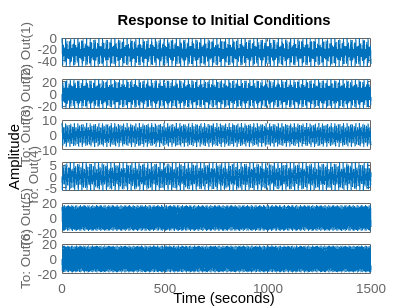

Desigining LQR for the linearized system.


K = 1.0e+03 *

    0.4472    1.1258    0.1113   -0.6999    0.2695   -0.2971


P = 1.0e+04 *

    0.0252    0.0277   -0.0157   -0.0497   -0.0066   -0.0284
    0.0277    0.0719    0.0103   -0.1564    0.0117   -0.0781
   -0.0157    0.0103    1.1194    0.0082    0.0114   -0.0515
   -0.0497   -0.1564    0.0082    2.3167    0.0619    0.0558
   -0.0066    0.0117    0.0114    0.0619    0.5857   -0.0128
   -0.0284   -0.0781   -0.0515    0.0558   -0.0128    0.6046


eigen =   -0.0213 + 0.7243i
  -0.0213 - 0.7243i
  -0.0464 + 1.0389i
  -0.0464 - 1.0389i
  -0.4628 + 0.4239i
  -0.4628 - 0.4239i


Considering K-gain matrix from LQR in state-space


state_space_lqr =
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1         0         1         0         0         0         0
   x2   -0.4472    -1.126    -1.111    0.6999     -1.27    0.2971
   x3         0         0         0         1         0         0
   x4  -0.02236  -0.05629   -0.5556     0.035  -0.06348   0.01486
   x5         0         0         0         0         0         1
   x6  -0.04472   -0.1126   -0.1111   0.06999    -1.127   0.02971
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
 
Continuous-time state-space model.



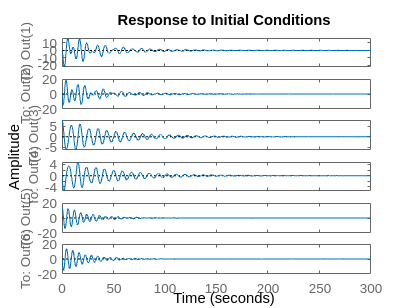


if CTR_rank == size(A,1)
    disp("Rank condition satisfied, system is stable.");
    
    %% Simulating linear system
    % Assuming we are measuring all the outputs
    C = eye(6)
    D = 0

    % Taking initial Q condition for LQR cost function
    Q = [100  0   0  0  0   0;
         0   80   0  0  0   0;
         0    0 200  0  0   0;
         0    0   0 80  0   0;
         0    0   0  0 50   0;
         0    0   0  0  0 300];
    R = 0.0005

    % Caculating initial state-space representation
    state_space_init = ss(A, B, C, D)

    disp("Taking Initial Conditions of the System");
    X_init = [0.1; 0; 8; 0; 15; 0]

    % Plot initial response of the system
    figure
    initial(state_space_init, X_init)

    disp("Desigining LQR for the linearized system.")
    [K P eigen] = lqr(A, B, Q, R)

    disp("Considering K-gain matrix from LQR in state-space")
    state_space_lqr = ss(A-(B*K),B, C, D)

    % Plotting response of the system with designed LQR
    figure
    initial(state_space_lqr, X_init)

else 
    disp("System is not stable.")
end